TN=tencom(y,u,r,init,varargin)

------------- Tensor completion given the inputs, outputs, TT-ranks, and TT initialization with scalar inputs

y = Outputs,

u = Inputs,

r = TT-ranks,

init = TT initialization.

Reference ---------

Fast and Accurate Tensor Completion with Tensor Trains: A System Identification Approach

clear all
% load housing
% filename = 'C:\Users\Ridvanz\Desktop\ThesisGit\Thesis\DATASETS\housing.csv';
% AA = readmatrix(filename);

filename = 'C:\Users\Ridvanz\Desktop\ThesisGit\Thesis\DATASETS\covtype';
AA = readmatrix(filename);



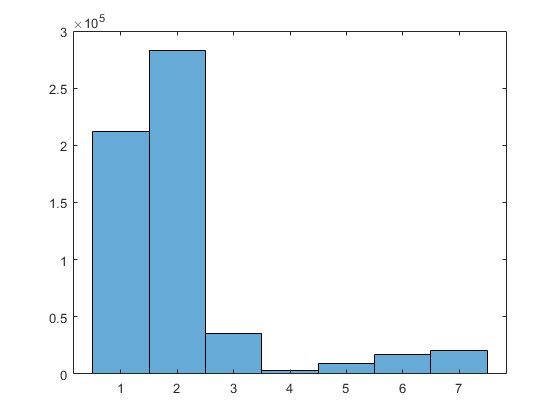


AA(AA(:,14)==50,:)=[];

histogram(AA(:,end)')

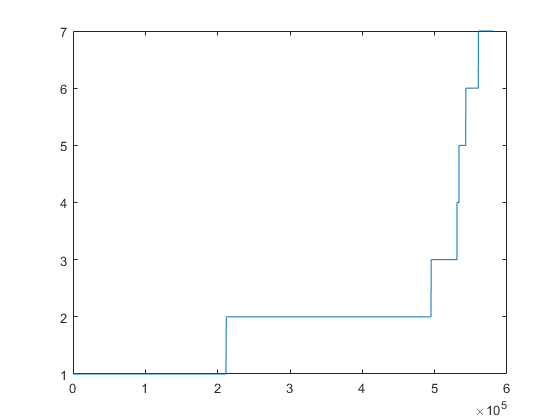


plot(sort(AA(:,end)'))

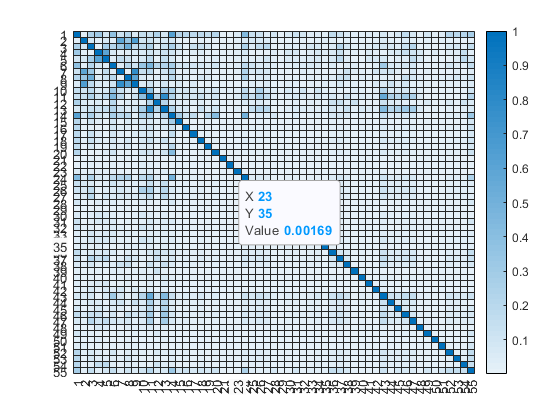

ans =   HeatmapChart with properties:

        XData: {55×1 cell}
        YData: {55×1 cell}
    ColorData: [55×55 double]

  Show all properties



heatmap(abs(corr(AA)))


inputamadre = normalize(AA);

max(abs(inputamadre))

ans =     3.9301    1.8259    6.9304    5.3050    9.5133    3.0571    7.9248   11.2966    3.7238    3.9214    1.1081    4.2944    1.1372    3.8362   13.8090    8.7299   10.9301    6.7728   19.0477    9.3470   74.3804   56.9638   22.4844    4.0993    6.7689    4.2879    5.6861   31.1283  440.0788   14.2556   12.9918   17.4630   11.9789    7.8582   26.3122    4.0509    3.0101    5.1289   34.9966   14.9471   23.1085   24.7624    2.0103    4.2729    4.6516    3.1722    3.4449   18.9645   17.5000   69.8673


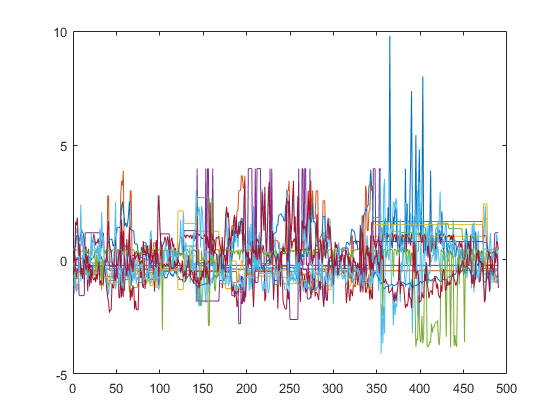


plot(inputamadre)

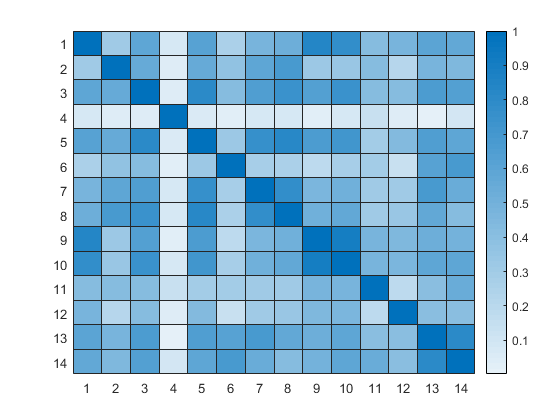

ans =   HeatmapChart with properties:

        XData: {14×1 cell}
        YData: {14×1 cell}
    ColorData: [14×14 double]

  Show all properties


gt = (1 + exp(-1*inputamadre)).^-1;

heatmap(abs(corr(gt)))

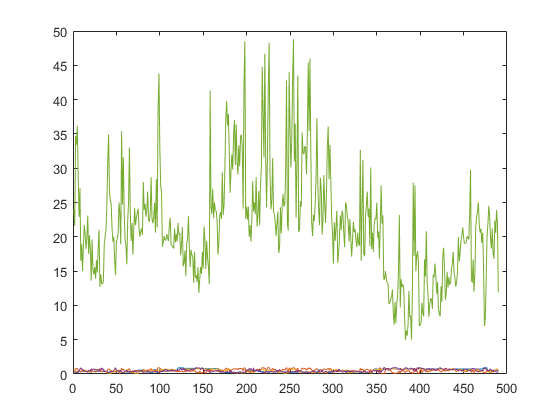

gt(:,4)=AA(:,4);
gt(:,end)=AA(:,end);
% gt(:,[4 6 8 10])=[];
gt=gt(:,[3 6 7 13 14]);
plot(gt);

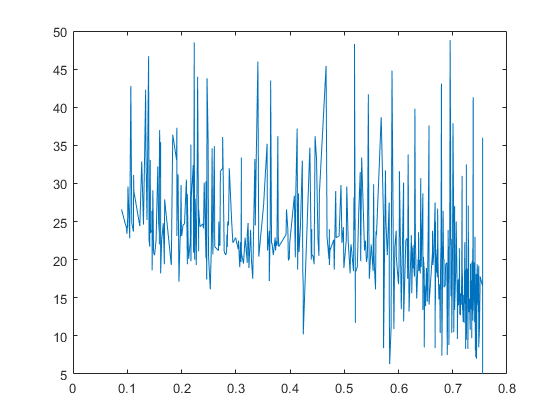


[sorto I]=sort(gt(:,end-2));
plot(sorto, gt(I,end));

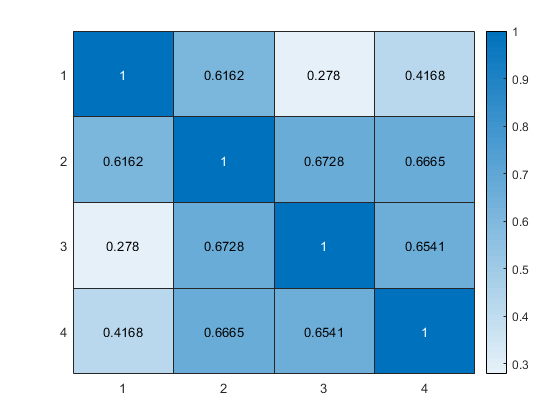


featurez=gt(1:end-51, 1:end-1);    tfeaturez=gt(end-50:end, 1:end-1);
featurez=gt(:, 1:end-1);
y=gt(1:end-51, end);    tlabels=gt(end-50:end, end);
y=gt(:, end);
a = featurez;
Covz = corr(featurez);
Z= 1-abs(Covz);
[optima, distas] = findorder(Z);
featurez = featurez(:,optima');
Z = corr(featurez);
heatmap(abs(Z));


tfeaturez = tfeaturez(:,optima');


[N, d]=size(featurez); 

nn = 3;  %degree B-spline
knotintervals = 7;
nnn= knotintervals+nn;

bs = bspline([0:nn+1]);
M = flipud(bs.coefs)';

knotdist = 1/knotintervals;

indexes = floor(featurez/knotdist)+1;
indexes(indexes>knotintervals)= knotintervals;

inputs = (featurez/knotdist)-indexes+1;
for i=1:d
bn = inputs(:,i).^[nn:-1:0]*M;

u{i} = zeros(N,nnn);
for ii=1:N
   u{i}(ii,indexes(ii):indexes(ii)+nn) = bn(ii,:);
end
end



Pcount = (nnn)^d

Pcount = 10000

% gamma=((N/Pcount^4))
% gamma=0

R = nnn^2;
R=20;
r=R*ones(1,d+1);

% %  r(d-1)=nnn^2;
r(1) = 1;  r(2)=nnn;  r(d)=nnn; r(d+1)=1;
disp(r)

     1    10    20    10     1




n=nnn*ones(1,d);

init=cell(1,d);
    for i=1:d
        init{i}.core=randn(r(i),n(i),r(i+1));
        init{i}.core=(init{i}.core/(norm(init{i}.core(:))));
        init{i}.r(1)=r(i);
        init{i}.n = n(i);
        init{i}.r(2)=r(i+1);
    end


   
    
% function TN=tencom(y,u,r,init,varargin)

% 2018, Ching-Yun KO

% N=size(u{1},1);
% d=size(u,2);                 

for i=1:d
    n(i)=size(u{i},2);
end
  

for i=1:d
    TN.core{i}=init{i}.core;
    TN.n(i,:)=[init{i}.r(1),init{i}.n,init{i}.r(2)];
end


Vp=cell(1,d);
Vm=cell(1,d);

Vm{1}=ones(N,1);
Vp{d}=ones(N,1);

% initialize right-orthonormal cores with prescribed TN ranks
for i=d:-1:2
    Vp{i-1}=dotkron(Vp{i},u{i})*reshape(permute(TN.core{i},[3 2 1]),[r(i+1)*n(i),r(i)]); 
end

difforder=2

difforder = 2

P = diff(eye(nnn),difforder);
PP = P'*P;

res1=[];
res2=[];
MAXITR = 4*d;

itr=1;                          % counts number of iterations
ltr=1;                          % flag that checks whether we sweep left to right
sweepindex=1;                   % index that indicates which TT core will be updated

gamma=0.0000001;
 tic
bbb=1;
% while itr<2 || ((e(itr) < e(itr-1)) && (itr < MAXITR) && e(itr) > THRESHOLD)
while itr<2 ||  (itr < MAXITR )
%     ---------------------updateTT-----------------;
            
nselect = floor(((itr+1)/MAXITR)^4*(N));
dataselect = randperm((N),nselect);
dataselect = 1:N;
    %         % first construct the linear subsystem matrix
        A=dotkron(Vm{sweepindex}(dataselect,:),u{sweepindex}(dataselect,:),Vp{sweepindex}(dataselect,:));
%         g=pinv(A'*A)*(A'*y(dataselect,:));
     
%         D = eye(r(sweepindex)*(n(sweepindex))*r(sweepindex+1)); 
                   
%         -------------------difference penalty 
        for j=1:d
        Csize = TN.n(j,:);
        
        Dm = reshape(permute(TN.core{j}, [2 1 3]), [Csize(2) Csize(1)*Csize(3)]);
        mDDm = reshape(Dm'*Dm, [Csize(1) Csize(3) Csize(1) Csize(3)]);
        DD{j} = reshape(permute(mDDm,[1 3 2 4]), [Csize(1)*Csize(1) Csize(3)*Csize(3)]);
        PD = P*Dm;
        DPPD = reshape(PD'*PD, [Csize(1) Csize(3) Csize(1) Csize(3)]);
        DWD{j} = reshape(permute(DPPD,[1 3 2 4]), [Csize(1)*Csize(1) Csize(3)*Csize(3)]);
        eyez{j}= reshape(eye(Csize(1)), [Csize(1)^2 1]);
        eyep{j}= reshape(eye(Csize(2)), [Csize(2)^2 1]);
        end
        eyez{d+1}=1;
        
        for p= 1:d
            Dsize = TN.n(sweepindex,:);   
                if sweepindex==p
                    D1 = eyez{sweepindex};
                    D2 = PP(:);
                    D3 = eyez{sweepindex+1};
                elseif sweepindex<p
                    D1 = eyez{sweepindex};  
                    D2 = eyep{sweepindex};   
                    D3= DWD{p}*eyez{p+1};           
                    for it=(p-1):-1:(sweepindex+1)               
                        D3 = DD{it}*D3;
                    end                               
                elseif sweepindex>p   
                    D1= eyez{p}'*DWD{p};
                    for it=(p+1):(sweepindex-1)               
                        D1 = D1*DD{it};
                    end
                    D1=D1';
                    D2 = eyep{sweepindex};   
                    D3= eyez{sweepindex+1}; 
                end
          
            WW = kron(D3, kron(D2, D1));
            Wtemp = permute(reshape(WW, [Dsize(1) Dsize(1) Dsize(2) Dsize(2) Dsize(3) Dsize(3)]), [1 3 5 2 4 6]);
            W{p} = reshape(Wtemp, [prod(Dsize) prod(Dsize)]); 
        end
        WWW = W{1};
        for s =2:d
            WWW = WWW + W{s};
        end
%         ----------------------- 
        
        g=pinv(A'*A + gamma*WWW)*(A'*y(dataselect,:));
testoro(bbb) = g'*g;
bbb=bbb+1;
        if ltr
            % left-to-right sweep, generate left orthogonal cores and update vk1
            TN.core{sweepindex}=reshape(g,[r(sweepindex),n(sweepindex),r(sweepindex+1)]);
            [Q,R]=qr(reshape(g,[r(sweepindex)*(n(sweepindex)),r(sweepindex+1)])); 
            TN.core{sweepindex}=reshape(Q(:,1:r(sweepindex+1)),[r(sweepindex),n(sweepindex),r(sweepindex+1)]);
            TN.core{sweepindex+1}=reshape(R(1:r(sweepindex+1),:)*reshape(TN.core{sweepindex+1},[r(sweepindex+1),(n(sweepindex+1))*r(sweepindex+2)]),[r(sweepindex+1),n(sweepindex+1),r(sweepindex+2)]);
            Vm{sweepindex+1}=dotkron(Vm{sweepindex},u{sweepindex})*reshape(TN.core{sweepindex},[r(sweepindex)*n(sweepindex),r(sweepindex+1)]); % N x r_{i}
        else
            % right-to-left sweep, generate right orthogonal cores and update vk2
            TN.core{sweepindex}=reshape(g,[r(sweepindex),n(sweepindex),r(sweepindex+1)]);
            [Q,R]=qr(reshape(g,[r(sweepindex),(n(sweepindex))*r(sweepindex+1)])'); 
            TN.core{sweepindex}=reshape(Q(:,1:r(sweepindex))',[r(sweepindex),n(sweepindex),r(sweepindex+1)]);
            TN.core{sweepindex-1}=reshape(reshape(TN.core{sweepindex-1},[r(sweepindex-1)*(n(sweepindex-1)),r(sweepindex)])*R(1:r(sweepindex),:)',[r(sweepindex-1),n(sweepindex-1),r(sweepindex)]);
            Vp{sweepindex-1}=dotkron(Vp{sweepindex},u{sweepindex})*reshape(permute(TN.core{sweepindex},[3 2 1]),[r(sweepindex+1)*n(sweepindex),r(sweepindex)]); % N x r_{i-1}    

        end
    
   %     ---------------------updatesweep-----------------; 
     
                if ltr
                    sweepindex=sweepindex+1;
                    if sweepindex== d                
                        ltr=0;
                        timer=toc;
                    end
                else
                    sweepindex=sweepindex-1;
                    if sweepindex== 1                
                        ltr=1;
                        timer=toc;
                    end
                end
    
    
        % only check residual after 1 half sweep
        if (sweepindex==d) || (sweepindex==1) % half a sweep
            
            res1(itr)=norm(A*g-y(dataselect,:))^2/(nselect); % check residual
            res2(itr)=1*(g'*g);
           
            if (itr>4)
%                 if (res1(itr)<1) || (abs(res1(itr)-res1(itr-2))<1)
%                  disp(res1(itr))
%                  break;
%                  end
            end
            
            itr=itr+1; %update iteration
            
            disp(["iteration:" itr timer])
        end   

        
end  

    "iteration:"    "2"    "5.8345"

    "iteration:"    "3"    "11.1576"

    "iteration:"    "4"    "16.6377"

    "iteration:"    "5"    "21.773"

    "iteration:"    "6"    "27.373"

    "iteration:"    "7"    "32.5857"

    "iteration:"    "8"    "37.6905"

    "iteration:"    "9"    "42.785"

    "iteration:"    "10"    "47.9039"

    "iteration:"    "11"    "53.1059"

    "iteration:"    "12"    "58.4362"

    "iteration:"    "13"    "63.8515"

    "iteration:"    "14"    "69.7308"

    "iteration:"    "15"    "75.0523"

    "iteration:"    "16"    "80.2138"



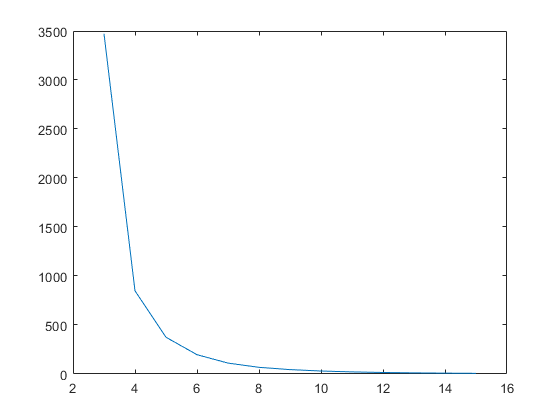

plot(res1)

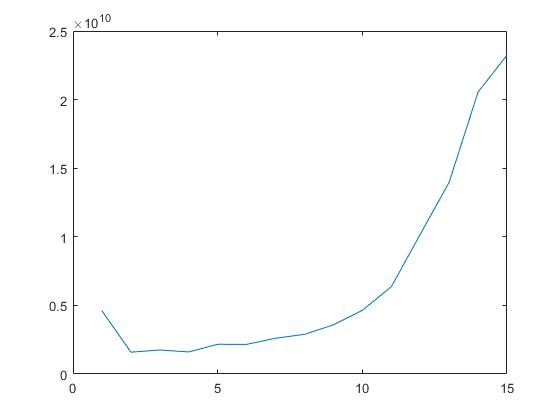

plot(res2)


[Nt, dt]=size(tfeaturez);

indexes = floor(tfeaturez/knotdist)+1;
indexes(indexes>knotintervals)= knotintervals;

inputs = (tfeaturez/knotdist)-indexes+1;
for i=1:dt
bn = inputs(:,i).^[nn:-1:0]*M;

ut{i} = zeros(Nt,nnn);
for ii=1:Nt
   ut{i}(ii,indexes(ii):indexes(ii)+nn) = bn(ii,:);
end
end

% [N, d]=size(featurez);

output=zeros(Nt,1);

G = TN.core;

for i = 1:length(G)
Gsize = [Nt size(G{i},1)  size(G{i},3)];
tempz = reshape(ut{i}*unfold(G{i},2), Gsize);
V{i} = permute(tempz, [2 3 1]);
end

output= zeros(Nt,1);

for jj=1:Nt   
f = (V{1});
f=1;
for i = 1:length(G)
f = f*V{i}(:,:,jj);
end
output(jj)=f';
end

[X,Y,Z] = peaks(25);

[X,Y] = meshgrid(tfeaturez(:,1),tfeaturez(:,2))

X =     0.6054    0.3983    0.3837    0.5212    0.4374    0.6676    0.5498    0.5274    0.6010    0.4860    0.3220    0.3895    0.4082    0.3801    0.3068    0.4700    0.4937    0.5728    0.7548    0.2222    0.4681    0.5903    0.1913    0.4769    0.4937    0.4987    0.6841    0.7771    0.3230    0.3605    0.5254    0.4498    0.3726    0.2294    0.2187    0.1462    0.4009    0.4009    0.3048    0.3801    0.2930    0.2125    0.3338    0.4142    0.2620    0.4171    0.6300    0.4521    0.7537    0.6984
    0.6054    0.3983    0.3837    0.5212    0.4374    0.6676    0.5498    0.5274    0.6010    0.4860    0.3220    0.3895    0.4082    0.3801    0.3068    0.4700    0.4937    0.5728    0.7548    0.2222    0.4681    0.5903    0.1913    0.4769    0.4937    0.4987    0.6841    0.7771    0.3230    0.3605    0.5254    0.4498    0.3726    0.2294    0.2187    0.1462    0.4009    0.4009    0.3048    0.3801    0.2930    0.2125    0.3338    0.4142    0.2620    0.4171    0.6300    0.4521    0.7537    0

Y =     0.6759    0.6759    0.6759    0.6759    0.6759    0.6759    0.6759    0.6759    0.6759    0.6759    0.6759    0.6759    0.6759    0.6759    0.6759    0.6759    0.6759    0.6759    0.6759    0.6759    0.6759    0.6759    0.6759    0.6759    0.6759    0.6759    0.6759    0.6759    0.6759    0.6759    0.6759    0.6759    0.6759    0.6759    0.6759    0.6759    0.6759    0.6759    0.6759    0.6759    0.6759    0.6759    0.6759    0.6759    0.6759    0.6759    0.6759    0.6759    0.6759    0.6759
    0.7025    0.7025    0.7025    0.7025    0.7025    0.7025    0.7025    0.7025    0.7025    0.7025    0.7025    0.7025    0.7025    0.7025    0.7025    0.7025    0.7025    0.7025    0.7025    0.7025    0.7025    0.7025    0.7025    0.7025    0.7025    0.7025    0.7025    0.7025    0.7025    0.7025    0.7025    0.7025    0.7025    0.7025    0.7025    0.7025    0.7025    0.7025    0.7025    0.7025    0.7025    0.7025    0.7025    0.7025    0.7025    0.7025    0.7025    0.7025    0.7025    0

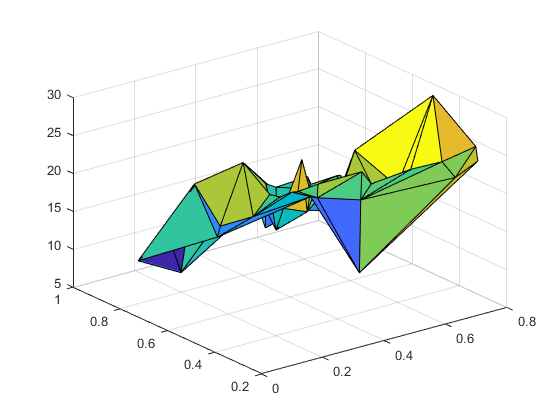


tri = delaunay(tfeaturez(:,1),tfeaturez(:,2));
h = trisurf(tri, tfeaturez(:,1), tfeaturez(:,2), tlabels);

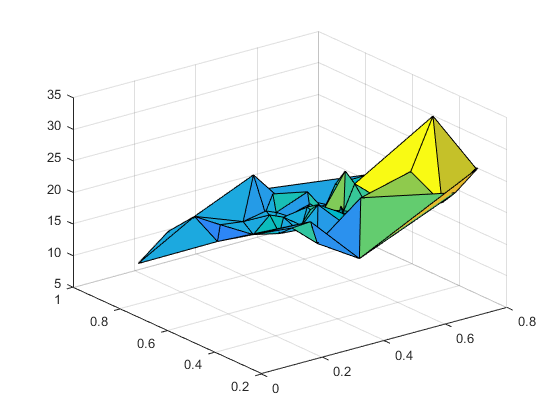

% scatter3(tfeaturez(:,1), tfeaturez(:,2), tlabels)

h = trisurf(tri, tfeaturez(:,1), tfeaturez(:,2), output);

% scatter3(tfeaturez(:,1), tfeaturez(:,2), output)

% axis vis3d

[tlabelz, id] = sort(tlabels);
outputsrt = output(id);

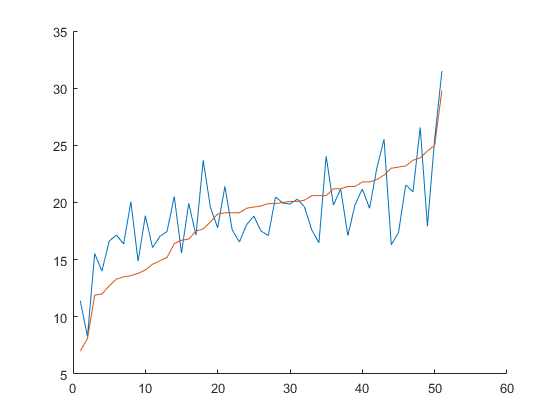



figure
hold on
plot(outputsrt)
plot(tlabelz)
hold off

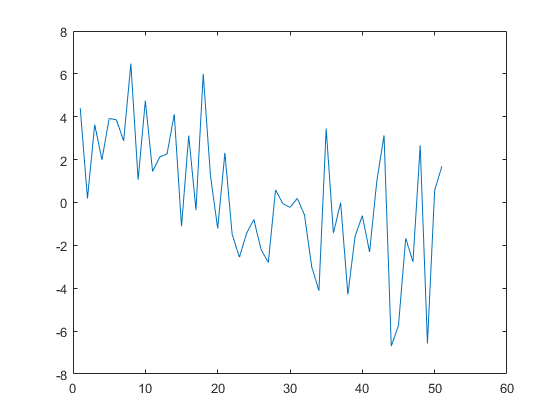

erboi = (outputsrt-tlabelz);
plot(erboi)

pererror = sum(abs(erboi))/Nt

pererror = 2.4437

relerror = sum(abs(erboi)/sum(tlabelz))

relerror = 0.1306

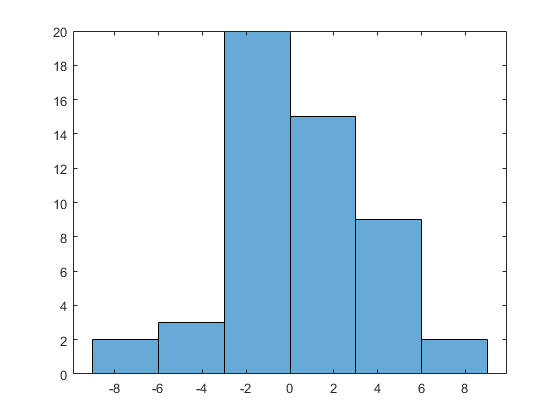

histogram((erboi)')


% % -------
% Vp=cell(1,d);
% Vm=cell(1,d);
% 
% Vm{1}=ones(N,1);
% Vp{d}=ones(N,1);
% 
% % initialize right-orthonormal cores with prescribed TN ranks
% for i=d:-1:2
%     Vp{i-1}=dotkron(Vp{i},u{i})*reshape(permute(TN.core{i},[3 2 1]),[r(i+1)*n(i),r(i)]); 
% end


difforder=2

difforder = 2

P = diff(eye(nnn),difforder)

P =      1    -2     1     0     0     0     0     0     0     0
     0     1    -2     1     0     0     0     0     0     0
     0     0     1    -2     1     0     0     0     0     0
     0     0     0     1    -2     1     0     0     0     0
     0     0     0     0     1    -2     1     0     0     0
     0     0     0     0     0     1    -2     1     0     0
     0     0     0     0     0     0     1    -2     1     0
     0     0     0     0     0     0     0     1    -2     1


PP = P'*P

PP =      1    -2     1     0     0     0     0     0     0     0
    -2     5    -4     1     0     0     0     0     0     0
     1    -4     6    -4     1     0     0     0     0     0
     0     1    -4     6    -4     1     0     0     0     0
     0     0     1    -4     6    -4     1     0     0     0
     0     0     0     1    -4     6    -4     1     0     0
     0     0     0     0     1    -4     6    -4     1     0
     0     0     0     0     0     1    -4     6    -4     1
     0     0     0     0     0     0     1    -4     5    -2
     0     0     0     0     0     0     0     1    -2     1



sweepindex=4

sweepindex = 4

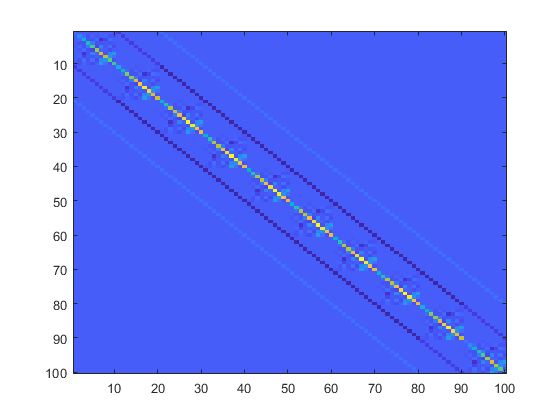

tic
for j=1:d
Csize = TN.n(j,:);

Dm = reshape(permute(G{j}, [2 1 3]), [Csize(2) Csize(1)*Csize(3)]);
mDDm = reshape(Dm'*Dm, [Csize(1) Csize(3) Csize(1) Csize(3)]);
DD{j} = reshape(permute(mDDm,[1 3 2 4]), [Csize(1)*Csize(1) Csize(3)*Csize(3)]);
PD = P*Dm;
DPPD = reshape(PD'*PD, [Csize(1) Csize(3) Csize(1) Csize(3)]);
DWD{j} = reshape(permute(DPPD,[1 3 2 4]), [Csize(1)*Csize(1) Csize(3)*Csize(3)]);
eyez{j}= reshape(eye(Csize(1)), [Csize(1)^2 1]);
eyep{j}= reshape(eye(Csize(2)), [Csize(2)^2 1]);
end
eyez{d+1}=1;

for p= 1:d
    Dsize = TN.n(sweepindex,:);   
        if sweepindex==p
            D1 = eyez{sweepindex};
            D2 = PP(:);
            D3 = eyez{sweepindex+1};

        elseif sweepindex<p
            D1 = eyez{sweepindex};  
            D2 = eyep{sweepindex};   
            D3= DWD{p}*eyez{p+1};           
            for it=(p-1):-1:(sweepindex+1)               
                D3 = DD{it}*D3;
            end                        
         
        elseif sweepindex>p   
            D1= eyez{p}'*DWD{p};
            for it=(p+1):(sweepindex-1)               
                D1 = D1*DD{it};
            end
            D1=D1';
            D2 = eyep{sweepindex};   
            D3= eyez{sweepindex+1}; 

        end
    
    WW = kron(D3, kron(D2, D1));
    Wtemp = permute(reshape(WW, [Dsize(1) Dsize(1) Dsize(2) Dsize(2) Dsize(3) Dsize(3)]), [1 3 5 2 4 6]);
    W{p} = reshape(Wtemp, [prod(Dsize) prod(Dsize)]);
    
end

WWW = W{1};
for s =2:d
    WWW = WWW + W{s};
end

imagesc(WWW)

% imagesc(W{d})
toc

Elapsed time is 0.050767 seconds.




% 
% 
% W =  permute(reshape(WW, c1 c1 c2 c2 c3 c3), [1 3 5 2 4 6]
% reshape(W, [c1*c2*c3 c4*c5*c6])


new = kron([2 2 2]',[1 2 3]')

new =      2
     4
     6
     2
     4
     6
     2
     4
     6


lef = [1 2 3]

lef =      1     2     3


mid =[1 2 3; 4 5 6; 7 8 9]

mid =      1     2     3
     4     5     6
     7     8     9


right =[2 2 2]'

right =      2
     2
     2


lef*mid *right

ans = 216


new(:)'*mid(:)

ans = 216